# Imu test

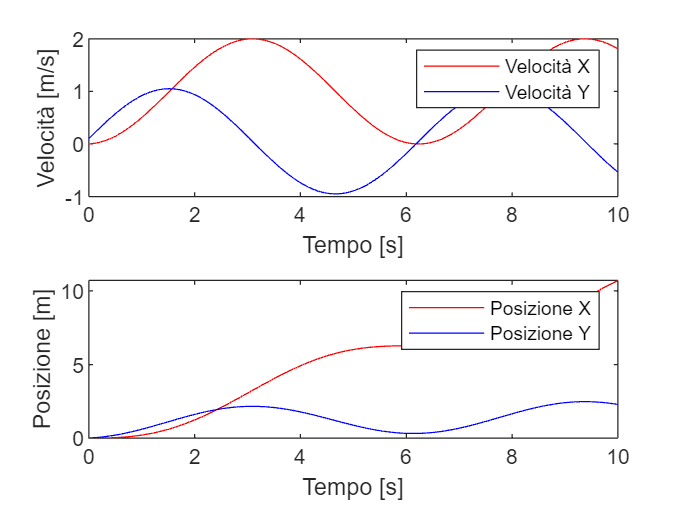

clear all;
clc;
% Dati IMU simulati
t = linspace(0, 10, 100); % tempo
acc_x = sin(t); % accelerazione lungo l'asse x
acc_y = cos(t); % accelerazione lungo l'asse y
gyros = ones(size(t)); % velocità angolare costante
orientation = cumsum(gyros) * (t(2) - t(1)); % integrando la velocità angolare

% Integrazione per calcolare velocità e posizione
dt = t(2) - t(1);
vel_x = cumsum(acc_x * dt); % velocità lungo l'asse x
pos_x = cumsum(vel_x * dt); % posizione lungo l'asse x

vel_y = cumsum(acc_y * dt); % velocità lungo l'asse y
pos_y = cumsum(vel_y * dt); % posizione lungo l'asse y

% Visualizzazione delle posizioni e delle velocità
figure;
subplot(2, 1, 1);
plot(t, vel_x, '-r', t, vel_y, '-b');
xlabel('Tempo [s]');
ylabel('Velocità [m/s]');
legend('Velocità X', 'Velocità Y');

subplot(2, 1, 2);
plot(t, pos_x, '-r', t, pos_y, '-b');
xlabel('Tempo [s]');
ylabel('Posizione [m]');
legend('Posizione X', 'Posizione Y');